# GENAVA INDEXING MECHANISM Analysis

## 1. Symbolic Variables

syms theta omega_in m N real
% theta    : Crank Angular Position
% omega_in : Crank Angular Velocity
N_val = 5; % Number of slots
R_val = 25; % Radius of Crank
d_val = 43.441; % Center distance between Crank and Geneva Wheel
m_val = d_val/R_val; % Dimension less geometry ratio

## 2. Geneva wheel (Output)

beta = atan2(sin(theta), m - cos(theta)); % Geneva wheel Angular Position in radians

% Find Angular Velocity of Geneva wheel using Chain Rule.
d_beta_d_theta = simplify(diff(beta, theta));
omega_out = d_beta_d_theta * omega_in;

% Find Angular Acceleration of Geneva wheel using Chain Rule.
d_omega_d_theta = simplify(diff(omega_out, theta));
alpha_out = d_omega_d_theta * omega_in;
 
omega_val = 1;   % Crank Angular velocity (rad/s)

theta_full_deg = linspace(-180, 180, 500);  % All angles are shown (Including dwell)
theta_full_rad = deg2rad(theta_full_deg);

engagement_idx = (theta_full_deg >= -54) & (theta_full_deg <= 54); % Engagement angle range [-54, 54] degrees

beta_full = zeros(size(theta_full_deg));
omega_full = zeros(size(theta_full_deg));
alpha_acc_full = zeros(size(theta_full_deg));

% Calculate values only for the engagement range
theta_active = theta_full_rad(engagement_idx);

% 1. Substitute values into beta (substitute m and theta)
beta_full(engagement_idx) = double(subs(subs(beta, m, m_val), theta, theta_active));

% 2. Substitute values into omega_out (substitute m, omega_in and theta)
omega_full(engagement_idx) = double(subs(subs(omega_out, [m, omega_in], [m_val, omega_val]), theta, theta_active));

% 3. Substitute values into alpha_out (substitute m, omega_in and theta)
alpha_acc_full(engagement_idx) = double(subs(subs(alpha_out, [m, omega_in], [m_val, omega_val]), theta, theta_active));

## Plot Graph

disp('Governing Equation for Angular Velocity Ratio:');

Governing Equation for Angular Velocity Ratio:


pretty(simplify(d_beta_d_theta))

$$\frac{m\,\cos\left(\theta \right)-1}{m^{2}-2\,\cos\left(\theta \right)\,m+1}$$

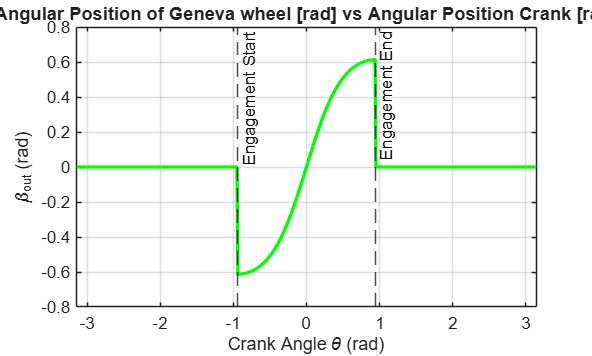


theta_boundary = deg2rad(54);

plot(theta_full_rad, beta_full, 'g-', 'LineWidth', 2);
axis([-pi,pi,-0.8,0.8]);
clear xline
xline(-theta_boundary, '--k', "Engagement Start");
xline(theta_boundary, '--k', "Engagement End");
title("Angular Position of Geneva wheel [rad] vs Angular Position Crank [rad]");
xlabel('Crank Angle \theta (rad)'); ylabel('\beta_{out} (rad)'); grid on;

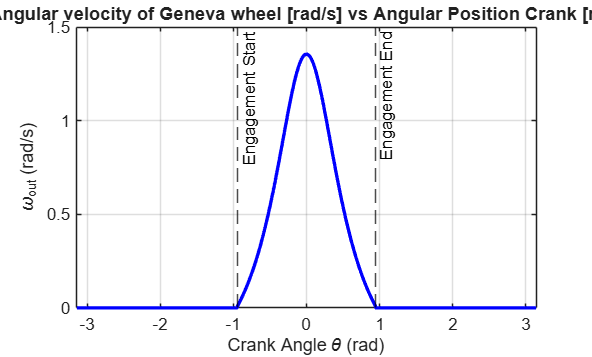


plot(theta_full_rad, omega_full, 'b-', 'LineWidth', 2);
axis([-pi,pi,0,1.5]);
xline(-theta_boundary, '--k', "Engagement Start");
xline(theta_boundary, '--k', "Engagement End");
title("Angular velocity of Geneva wheel [rad/s] vs Angular Position Crank [rad]");
xlabel('Crank Angle \theta (rad)'); ylabel('\omega_{out} (rad/s)'); grid on;

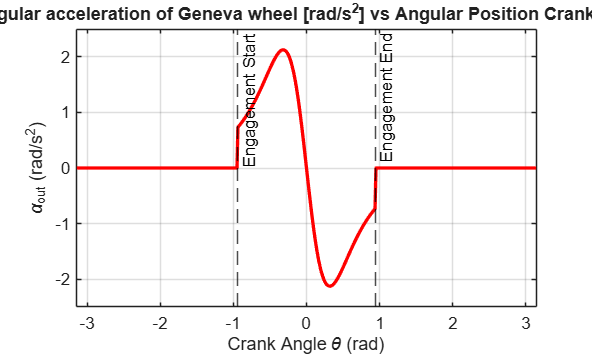



plot(theta_full_rad, alpha_acc_full, 'r-', 'LineWidth', 2);
axis([-pi,pi,-2.5,2.5]);
xline(-theta_boundary, '--k', "Engagement Start");
xline(theta_boundary, '--k', "Engagement End");
title("Angular acceleration of Geneva wheel [rad/s^2] vs Angular Position Crank [rad]");
xlabel('Crank Angle \theta (rad)'); ylabel('\alpha_{out} (rad/s^2)'); grid on;

# Mechanism Kinematic and Discussion

- Number of slots = 5

#### 1. Angular Position (β)

- During dwell  angular position range (θ < -0.94 rad and θ > 0.94 rad ), the angular position of Geneva wheel remains at 0 rad (the wheel is locked and stationary).

- When the drive pin enters the slots (θ **≈** 0.94 rad), the Geneva wheel starts rotating, sweeping an angle from  β  **≈ **-0.62 rad to β **≈ **0.62 rad.

#### 2. Angular Velocity (ω)

- The maximum angular velocity occurs at the midpoint of engagement (θ = 0), reaching a peak value of ω **≈ **1.35 rad/s.

#### 3. Angular Acceleration (α)

- An angular acceleration discontinuity occurs at the entry and exit of engagement. This abrupt change results in infinite jerk, causing impact loading and vibration in practical mechanical operations.